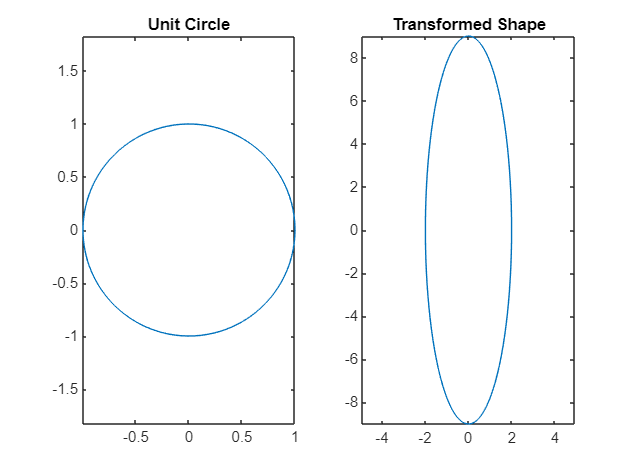

%Visualization how a matrix transforms the unit circle 
A = [2 0;0 9];
%create unit circle 
theta=linspace(0,2*pi,100);
x=cos(theta);
y=sin(theta);
circle=[x;y];

%apply transformation 
transformed=A*circle;

%plot
figure;
subplot(1,2,1);
plot(circle(1,:),circle(2,:));
title('Unit Circle');
axis equal;

subplot(1,2,2);
plot(transformed(1,:),transformed(2,:));
title('Transformed Shape');
axis equal;

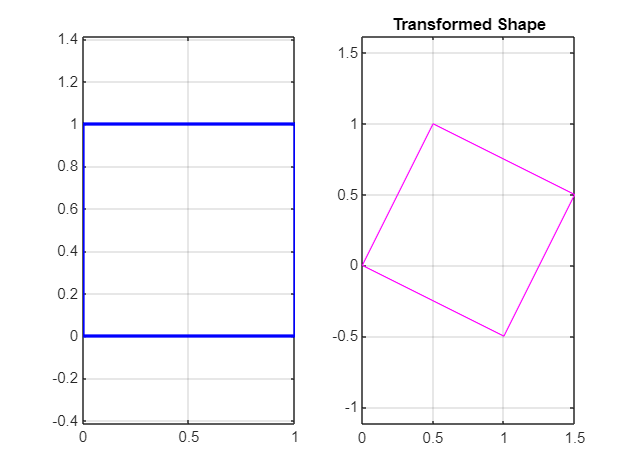

%Visualization how a matrix transformers a square
A = [1 0.5;-0.5 1];%transformed matrix
%Create square vertices 
square=[0 1 1 0 0;0 0 1 1 0];

%Apply transformation 
transformed=A*square;

%plot 
figure;
subplot(1,2,1);
plot(square(1,:),square(2,:),'b-','LineWidth',2);
axis equal;
grid on;

subplot(1,2,2);
plot(transformed(1,:),transformed(2,:),'m');
title('Transformed Shape');
axis equal;
grid on;

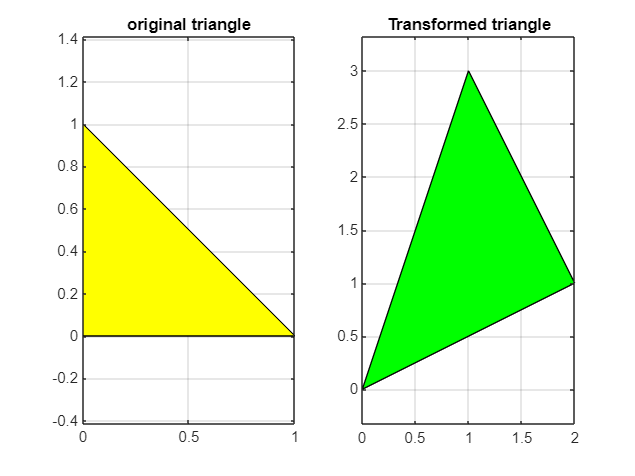

%Visualization how a matrix transformers a square
A = [1 2;3 1]; %example transformed matrix

%create triangle vertices 
triangle = [0 1 0 0 ; 0 0 1 0];

%apply transformation
transformed = A*triangle ;

%plot 
figure;
subplot(1,2,1);
fill(triangle(1,:),triangle(2,:),'y');
title('original triangle');
axis equal;
grid on;

subplot(1,2,2);
fill(transformed(1,:),transformed(2,:),'g');
title('Transformed triangle');
axis equal;
grid on;

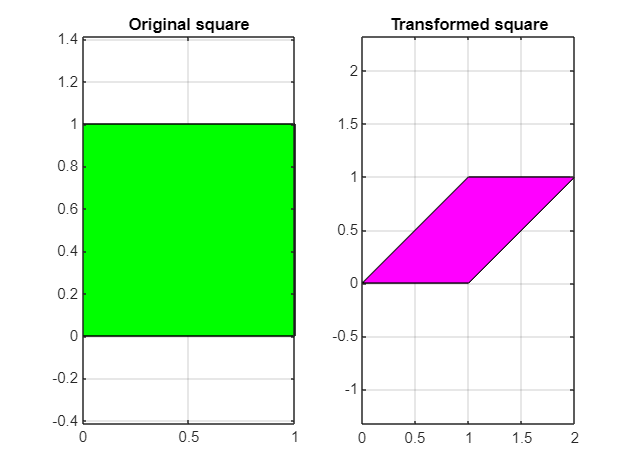




% Visualization of how a matrix transforms a square
% Transformation matrix
A = [1 1; 0 1]; %This is a valid 2x2 matrix

% Create square vertices (4 corners)
% Square from (0,0) to (1,1)
square = [0 1 1 0 0;   % x-coordinates
          0 0 1 1 0];  % y-coordinates

%Apply transformation
transformed = A * square;

%Plot the original and transformed shapes
figure;

% Original Square 
subplot(1, 2, 1);
fill(square(1,:),square(2,:),'g');
title('Original square');
axis equal;
grid on;

% Transformed square
subplot(1, 2, 2);
fill(transformed(1,:),transformed(2,:),'m');
title('Transformed square');
axis equal;
grid on;